# Lab 1

Adel Bavey

1.3 Basis functions

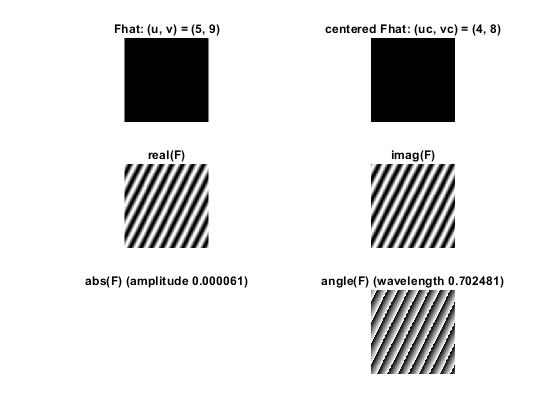


fftwave(5,9,128)

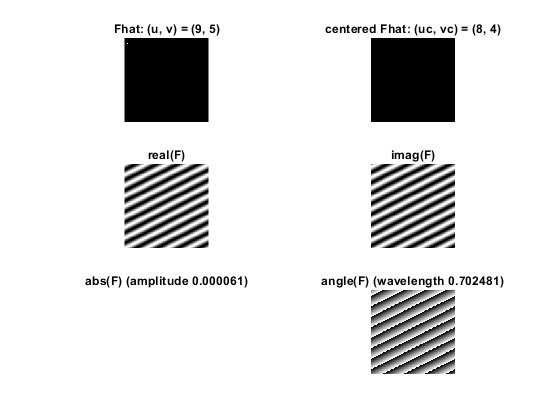

fftwave(9,5,128)

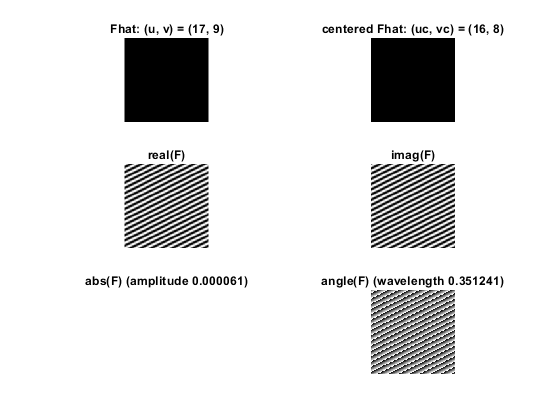

fftwave(17,9,128)

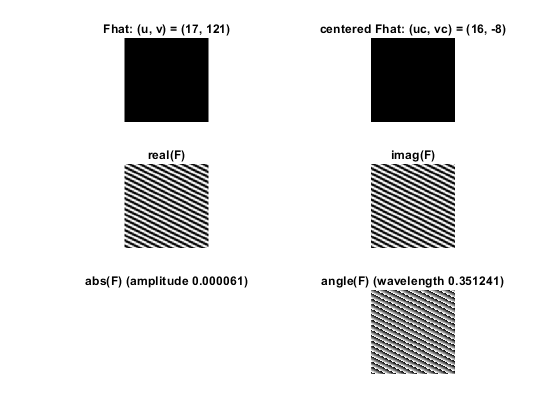

fftwave(17,121,128)

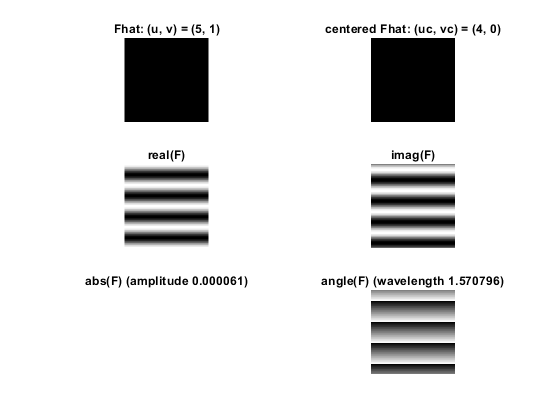

fftwave(5,1,128)

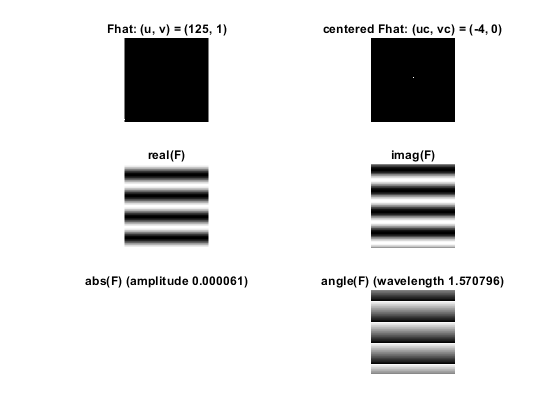

fftwave(125,1,128)

1.4 Linearity

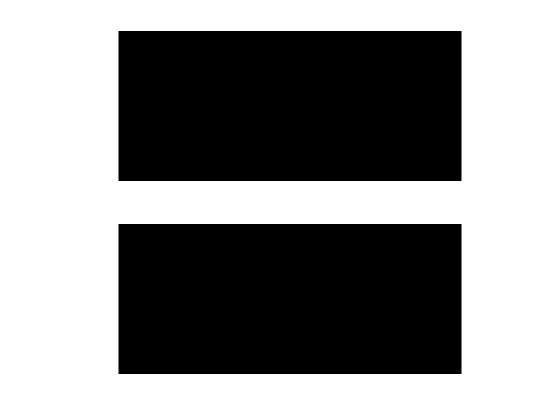


F = [ zeros(56, 128); ones(16, 128); zeros(56, 128)];
G = F';
H = F + 2 * G;

subplot
showgrey(F)

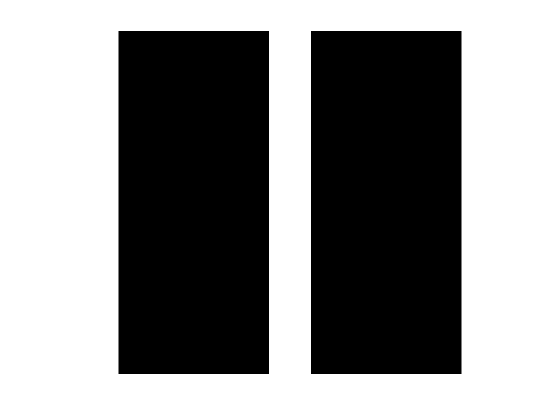

showgrey(G)

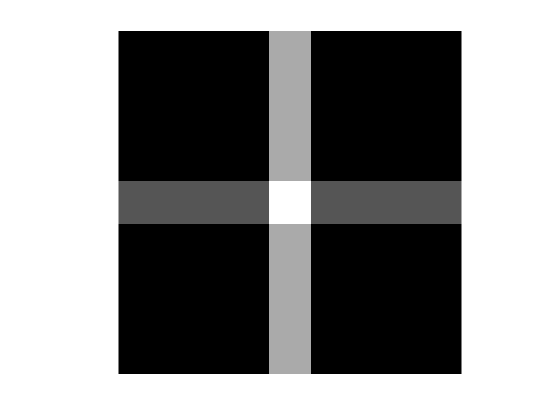

showgrey(H)

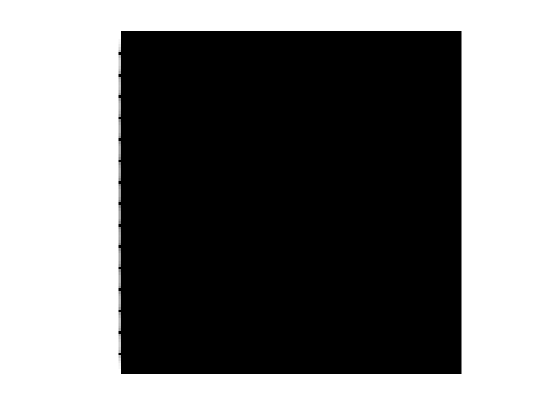


Fhat = fft2(F);
Ghat = fft2(G);
Hhat = fft2(H);

showgrey(log(1 + abs(Fhat)));

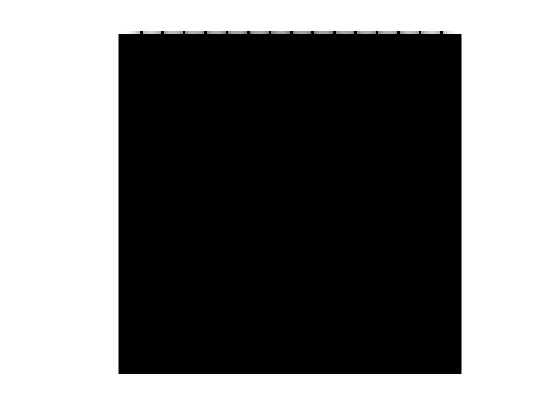

showgrey(log(1 + abs(Ghat)));

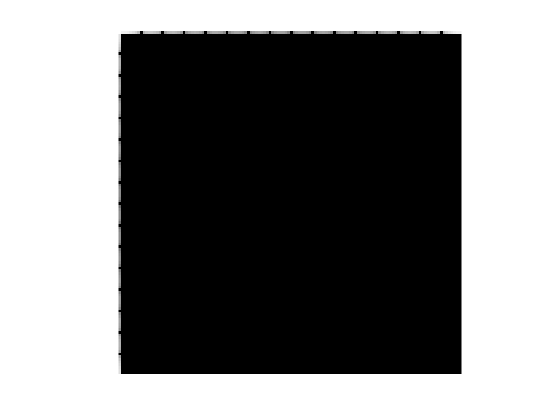

showgrey(log(1 + abs(Hhat)));

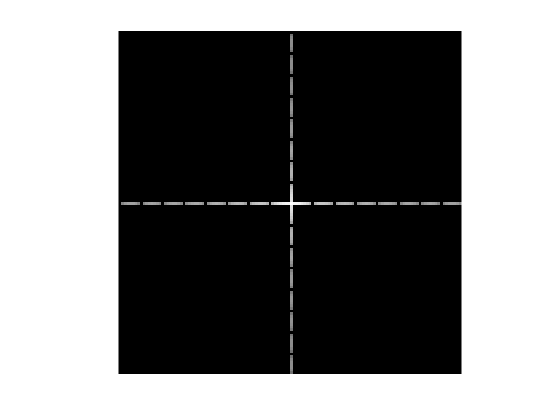

showgrey(log(1 + abs(fftshift(Hhat))));

1.5 Multiplication

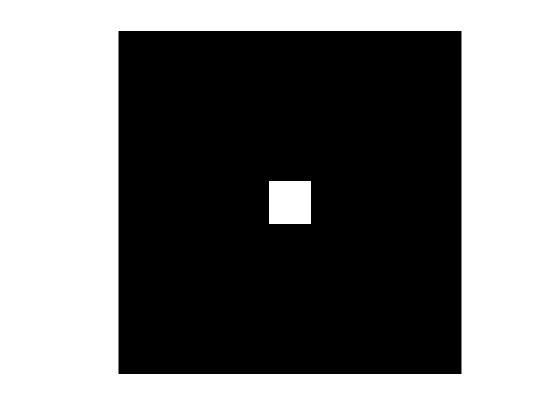


F = [ zeros(56, 128); ones(16, 128); zeros(56, 128)];
G = F';

subplot
showgrey(F .* G);

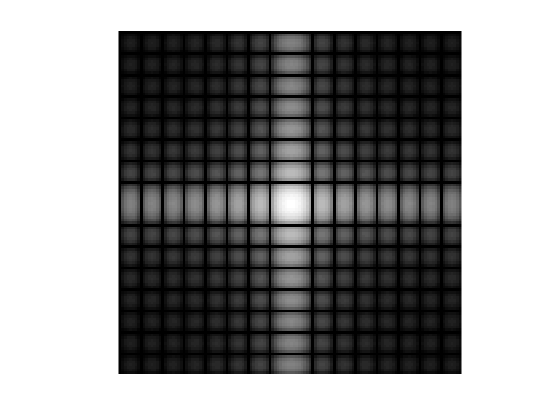

showfs(fft2(F .* G));

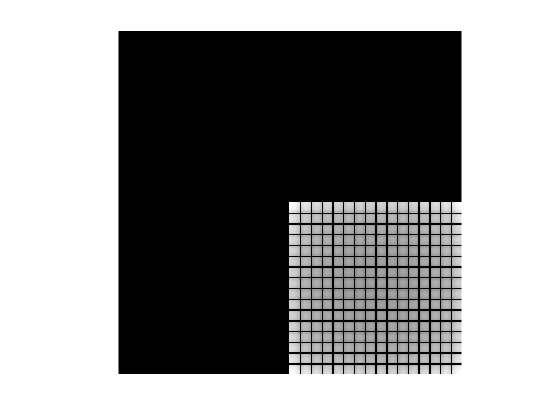

showfs(conv2(fft2(F),fft2(G)));

1.6 Scaling

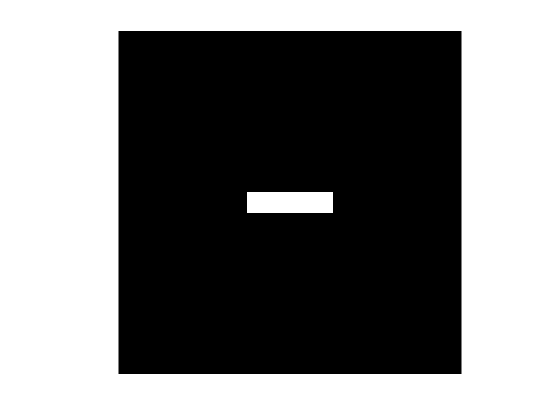


Forig =[ zeros(56, 128); ones(16, 128); zeros(56, 128)];

F = [zeros(60, 128); ones(8, 128); zeros(60, 128)] .* ...
[zeros(128, 48) ones(128, 32) zeros(128, 48)];

showgrey(F)

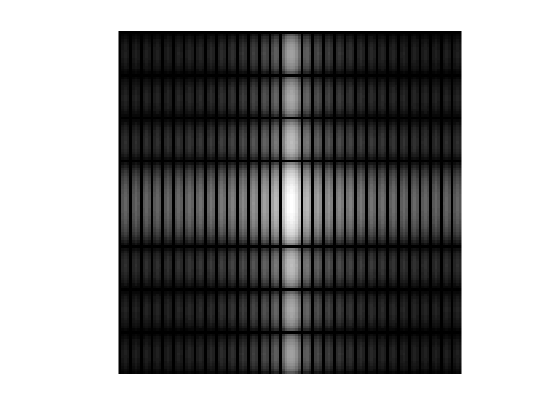

showfs(fft2(F))


showgrey(Forig)

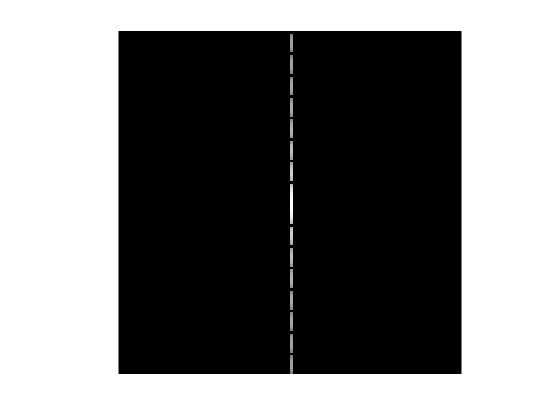

showfs(fft2(Forig))

1.7 Rotation


figure
alpha = 30

alpha = 30

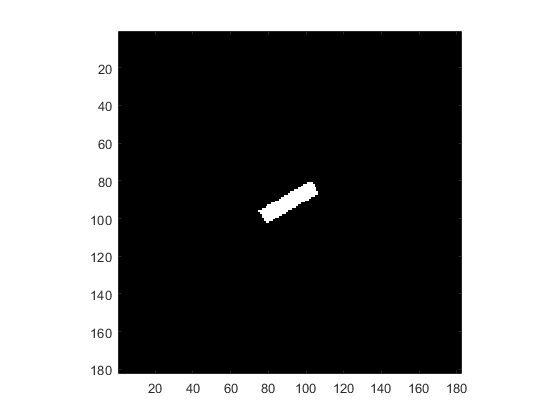

G = rot(F, alpha );
showgrey(G)
axis on

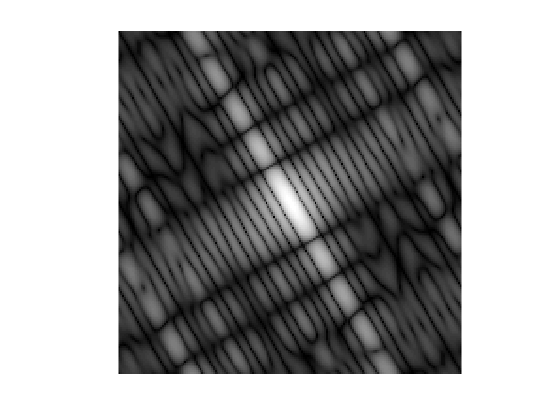

Ghat = fft2(G);
showfs(Ghat)

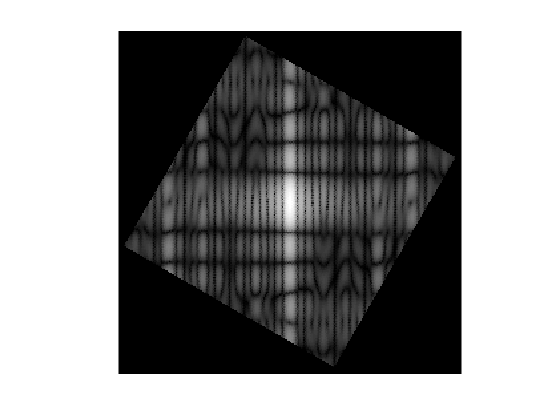

Hhat = rot(fftshift(Ghat), -alpha );
showgrey(log(1 + abs(Hhat)))